## Step 1: Define System and Parameters    

clear all; clc
% True system parameters (unknown to the algorithm)
A = [0 1; -1 -0.5]; % True system matrix A (unknown to the algorithm)
B = [0 0; 1 1];     % True input matrix B (unknown to the algorithm)

% Cost function matrices
Q = eye(2);         % State weighting matrix
R = eye(2);         % Control weighting matrix

% Time step for real-time operation
dt = 0.01;          % Time step size

% Simulation time
tspan = 0:dt:10;    % Simulation time span

% Initial state
x0 = [1; 0];        % Initial state vector

##  Step 2: Define the System Dynamics

% System dynamics (unknown to the algorithm)
sys_dynamics = @(t, x, u) A * x + B * u;


## step 3: Define the Cost Function

% Cost function
cost_function = @(x, u) x' * Q * x + u' * R * u;

## Step 4: Initialize Actor and Critic Parameters

% Initial control policy (Actor)
K = zeros(2, 2);    % Initial control gain matrix (2 inputs, 2 states)

% Initial value function parameters (Critic)
P = zeros(2, 2);    % Initial value function matrix

% Actor-Critic parameters
alpha_actor = 0.01; % Learning rate for Actor
alpha_critic = 0.01; % Learning rate for Critic
gamma = 0.99;       % Discount factor
exploration_noise = 0.1; % Exploration noise (e.g., Gaussian noise)

  ***Why add some noise into the optimal policy? they say "exploration noise"*** 

## Step 5: Real-Time Actor-Critic Algorithm

% Initialize state and time
x = x0;             % Initial state
x_history = zeros(2, length(tspan)); % To store state history
u_history = zeros(2, length(tspan)); % To store control history (2 inputs)

% Main real-time Actor-Critic loop
for t = 1:length(tspan)
    % Apply control input with exploration noise
    u = -K * x + exploration_noise * randn(2, 1); % Add exploration noise
    u_history(:, t) = u; % Store the control input (vector)
    
    % Simulate the system for one time step
    x_dot = sys_dynamics(tspan(t), x, u);
    x_next = x + x_dot * dt;
    
    % Compute the reward
    r = cost_function(x, u);
    
    % Critic Update: Estimate the value function
    delta = r + gamma * x_next' * P * x_next - x' * P * x;
    P = P + alpha_critic * delta * (x * x');
    
    % Actor Update: Improve the control policy
    K = K - alpha_actor * delta * (x * u');
    
    % Update the state
    x = x_next;
    x_history(:, t) = x;
end

1) In Critic Update (see Actor_Critic) using gradient descent value up-date

                      
$$\mathrm{P}\mathrm{\ }=\mathrm{P}+\alpha_{\mathrm{c}\mathrm{r}\mathrm{i}\mathrm{t}\mathrm{i}\mathrm{c}} \delta \left(\mathrm{x}{\mathrm{x}}^{\mathrm{T}} \right)$$


    where $\delta \;$is TD error, $\mathrm{x}{\mathrm{x}}^{\mathrm{T}}$ is outer product which is the gradient of the value respect to P

    - dis advantage: slow convergence rate and high variance if noisy measurements

2) In Actor update(improve ment) 

  here  without $\left(A,B\right)$ especially $B$, the IRL controller is a state feedback as 

                            
$$K=K-\alpha \;\delta \;\textrm{xu}$$


  the cross product $\left(\textrm{xu}\right)$ is similar to the output product for correlation of the states and input. 

 However, in case of non-minimum phase, it may be reversed. 

 To remedy this ( in non-minimum phase), 

- More Sophisticated Policy Gradient Methods: Methods like TRPO (Trust Region Policy Optimization), PPO (Proximal Policy Optimization), and DDPG (Deep Deterministic Policy Gradient) use more sophisticated gradient estimators that are less susceptible to the misleading effects of immediate responses. These methods often involve:

- Estimating the Advantage Function: Instead of directly using the TD error, they estimate the *advantage function*, which measures how much better an action is compared to the average action in that state. This can help to filter out the noise caused by immediate, but ultimately misleading, responses.

- Using Baselines: Subtracting a baseline from the TD error can reduce variance and improve the accuracy of the gradient estimate.

- Trust Region Constraints: TRPO and PPO constrain the size of the policy update to prevent large changes that could destabilize learning.

- Recurrent Neural Networks (RNNs): RNNs can capture temporal dependencies in the system's dynamics. By using an RNN to represent the actor or critic, the agent can learn to "remember" past actions and states, and to predict the long-term effects of its actions.

- System Identification: If possible, try to identify a more accurate model of the system's dynamics. This model can then be used to design a more robust controller.

- Careful Reward Shaping: Design the reward function to encourage the desired long-term behavior, even if it means tolerating some initial "wrong way" movements.

- Delay Compensation: Techniques like Smith Predictors can be used to compensate for the time delays introduced by non-minimum phase behavior.

%% Comments;

  In Unscented Kalman filter, the Kalman gain is used the cross product. 

  
$$K_{\textrm{Kalman}\;\;} \sim \frac{\textrm{belief}\;\textrm{in}\;\textrm{state}}{\textrm{belief}\;\textrm{in}\;\textrm{measurement}}=P_{\textrm{xz}} P^{-1\;} =\sum {\left\lbrack w^{c\;} \left(\Upsilon -\bar{x} \right)\left(Z-u_{z\;} \right)\right\rbrack }^{T\;} P_z^{-1\;} \;$$


# ** Kim's claim is : it is better to use "Unscented transformation" **

## Step 6: Plot the Results

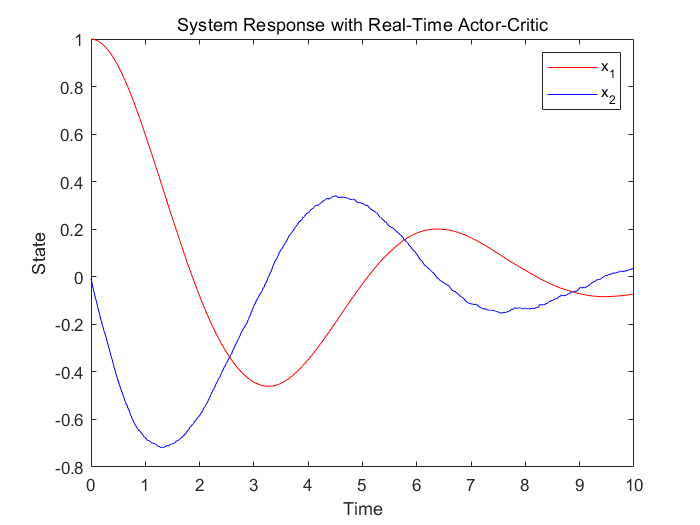

% Plot the system response
figure;
plot(tspan, x_history(1, :), 'r', tspan, x_history(2, :), 'b');
xlabel('Time');
ylabel('State');
legend('x_1', 'x_2');
title('System Response with Real-Time Actor-Critic');

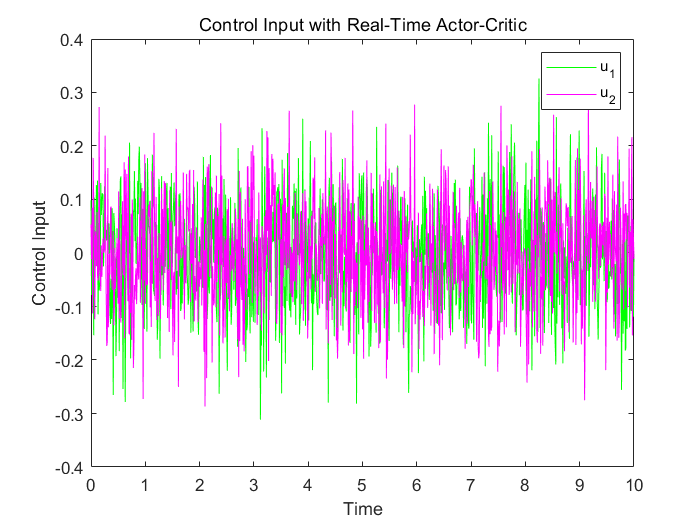


% Plot the control input
figure;
plot(tspan, u_history(1, :), 'g', tspan, u_history(2, :), 'm');
xlabel('Time');
ylabel('Control Input');
legend('u_1', 'u_2');
title('Control Input with Real-Time Actor-Critic');

   Comments

   In this example, the trajectories are similar to the those of the identification. however, the contol input is** very noisy since the measurements of the states are noisy. Is it good for real even if LQR is  noisy?**